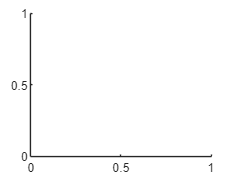

clc; cla; clear

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                     Scan Parameters to be adjusted               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A standard suite is to run 
% channel=3, has_sample=0
% channel=1, has_sample=0
% channel=1, has_sample=1
%IMPORTANT:Set this parameter from Vigo outputs! BAL = 1; SIG = 2; REF = 3
channel=1;
%IMPORTANT:Set this parameter to Blank (0) or Sample (1):
has_sample=0;
%IMPORTANT: Set this directory to know where to save data to
save_dir="C:\save_dir\";
%IMPORTANT: Set this directory to access MIRcat SDK code (from Daylight Solutions)
run_dir="C:\run_dir\";

save_dir = "C:\Users\Boxer Lab\Desktop\Laser Tests\070424_benzonitrile_scan_tests\water_250um"

run_dir = "C:\Users\Boxer Lab\Desktop\MIRCat_FLASHDRIVE\MIRcatSDKCodeExample-MATLAB\MIRcatSDKCodeExample-MATLAB\"

cd(run_dir);
hfile ='MIRcatSDK.h';  % Denote the location of the headerfile

% Use of MIRcat SDK scripts:
% ret is the return value% Function_Name is the name of the MIRcatSDK function you would like to call.
% For example, `MIRcatSDK_StartSweepScan`% Variables are comma separated and are listed after the function name
% ret = calllib('MIRcatSDK','Function_Name', variable1, variable2)

% SR865A Scan Parameters
global num_points kb rate startWL laser_rate repetitions
%Set this parameter to the size (in kb) of the data buffer:
kb=16; % Must be an even number, up to 64 (default = 32). 
num_points=128*kb;
% Set rate to power of 2 by which to divide the SR865A maximum capture rate. 
rate = 4; 
% For each increase of time constant on lock-in, can decrease "rate" by 1, and vice versa.
% Note SR865A default time constant should be 300 microseconds (resolution = 0.6 cm-1), input range 1 V, 500 mV sensitivity
% MIRcat parameter defaults: 30% Duty cycle, 1 MHz, 780 mA current
% Set scan parameters (default scan direction is high-freq to low-freq)
startWL = 2360; % Starting scan direction
laser_rate=2000; % Laser scan rate in cm-1 per second
repetitions=16; % Number of scans

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                    Load Laser Control Library                    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('========================================================\n');

fprintf('Quering API Version ... ');

Quering API Version ... 

% Create your variables and Pointers if necessary.
[notfound,warnings]=loadlibrary('libs/MIRcatSDK',hfile,'alias','MIRcatSDK');
load('MIRcatSDKconstants.mat');% Load the constants from the SDK
major = uint16(0);
majorPtr = libpointer('uint16Ptr', major);
minor = uint16(0);
minorPtr = libpointer('uint16Ptr', minor);
patch = uint16(0);
patchPtr = libpointer('uint16Ptr', patch);
% Call the function
ret = calllib('MIRcatSDK','MIRcatSDK_GetAPIVersion', majorPtr, minorPtr, patchPtr);
% Checkto see if function call was Successful
if MIRcatSDK_RET_SUCCESS == ret
    fprintf('Successful\n');
else
    % If the operation fails, unload the library and raise an error.
    unloadlibrary MIRcatSDK;
    error('Error! Code: %d', ret);
end

Successful


% Convert the pointer values to the original variables.
major = majorPtr.value;
minor = minorPtr.value;
patch = patchPtr.value;
fprintf(' API Version: %d.%d.%d\n', major, minor, patch);

 API Version: 1.5.2


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                  Initialize MIRcat and SR865A                    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Connecting to MIRcat
fprintf('========================================================\n');

fprintf('Initializing MIRcat ... ');

Initializing MIRcat ... 

% Call your function
ret = calllib('MIRcatSDK','MIRcatSDK_Initialize');
% Check to see if function call was Successful
if MIRcatSDK_RET_SUCCESS == ret
    fprintf('Successful\n');
else
    % If the operation fails, unload the library and raise an error.
    unloadlibrary MIRcatSDK;
    error('Error! Code: %d', ret);
end

Successful



%Scan initialization procedure
% Step 1: Get the number of installed QCLs
fprintf('========================================================\n');

fprintf('Test: How many QCLs are installed? ... ');

Test: How many QCLs are installed? ... 

numQCLs =uint8(0);
numQCLsPtr = libpointer('uint8Ptr', numQCLs);
calllib('MIRcatSDK','MIRcatSDK_GetNumInstalledQcls', numQCLsPtr);
numQCLs = numQCLsPtr.value;
fprintf(' %d\n', numQCLs);

 2




% Step 2: Check for Interlock Status
fprintf('========================================================\n');

fprintf('Test: Is Interlock Set ... ');

Test: Is Interlock Set ... 

isInterlockSet = false;
isInterlockSetPtr = libpointer('bool', isInterlockSet);
ret = calllib('MIRcatSDK','MIRcatSDK_IsInterlockedStatusSet', isInterlockSetPtr);
isInterlockSet = isInterlockSetPtr.value;
if logical(isInterlockSet)
    fprintf(' Yes\n' );
else
    % If the operation fails, unload the library and raise an error.
    fprintf(' NO\n' );
    calllib('MIRcatSDK','MIRcatSDK_DeInitialize');
    unloadlibrary MIRcatSDK;
    error('Error! Interlock is not set. Code: %d', ret);
end

 Yes



% Step 3: Check for Key Switch Status
fprintf('========================================================\n');

fprintf('Test: Is Key Switch Set ... ');

Test: Is Key Switch Set ... 

isKeySwitchSet = false;
isKeySwitchSetPtr = libpointer('bool', isKeySwitchSet);
ret = calllib('MIRcatSDK','MIRcatSDK_IsKeySwitchStatusSet', isKeySwitchSetPtr);
isKeySwitchSet = isKeySwitchSetPtr.value;
if logical(isKeySwitchSet)
    fprintf(' Yes\n' );
else
    % If the operation fails, unload the library and raise an error.
    fprintf(' NO\n' );
    calllib('MIRcatSDK','MIRcatSDK_DeInitialize');
    unloadlibrary MIRcatSDK;
    error('Error! KeySwitch is not set. Code: %d', ret);
end

 Yes




% SR865A Initialization
v=visadev("TCPIP0::192.168.0.4::inst0::INSTR") % First enter telnet 192.168.0.4 into Windows terminal

v =   TCPIP with properties:

         ResourceName: "TCPIP0::192.168.0.4::inst0::INSTR"
                Alias: ""
               Vendor: "Stanford_Research_Systems"
                Model: "SR865A"
              LANName: "inst0"
    InstrumentAddress: "192.168.0.4"
    NumBytesAvailable: 0

  Show all properties, functions


% v=visadev('USB0::0xB506::0x2000::004559::0::INSTR') % for USB
writeread(v,"*IDN?")

ans = "Stanford_Research_Systems,SR865A,004559,V1.51"

write(v,'CAPTURELEN ' + string(kb))
write(v,'CAPTURECFG 1') % 1 for X and Y, 2 for R and theta
write(v,'CAPTURERATE ' + string (rate))
capturerate=str2double(writeread(v,'CAPTURERATE?'))

capturerate = 9.7656e+03

% clear v;
   
x_matrix=zeros([kb*128,repetitions]);
y_matrix=zeros([kb*128,repetitions]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          Arm the Laser                           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Step 4: Arm the laser
fprintf('========================================================\n');

fprintf('Test: Arm Laser ... ');

Test: Arm Laser ... 

isArmed = false;
isArmedPtr = libpointer('bool', isArmed);
calllib('MIRcatSDK','MIRcatSDK_IsLaserArmed', isArmedPtr);
isArmed = isArmedPtr.value;

if ~isArmed
    ret = calllib('MIRcatSDK','MIRcatSDK_ArmDisarmLaser');
    if MIRcatSDK_RET_SUCCESS == ret
        fprintf(' Successful\n' );
        fprintf('========================================================\n');
        fprintf('Test: Is Laser Armed?\n');
    else
        % If the operation fails, unload the library and raise an error.
        fprintf(' Failure\n');
        unloadlibrary MIRcatSDK;
        error('Error! Code: %d', ret);
    end
else
    fprintf(' Already Armed\n ');
end

 Already Armed
 


while ~isArmed
    calllib('MIRcatSDK','MIRcatSDK_IsLaserArmed', isArmedPtr);
    isArmed = isArmedPtr.value;
    if logical(isArmed)
        fprintf('\tTrue\n' );
    else
        fprintf('\tFalse\n');
    end
    pause(1.0);
end

% Step 5: Wait for TECs to arrive at safe operating temperature
fprintf('========================================================\n');

fprintf('Are TECs at Safe Operating Temp? ... \n');

Are TECs at Safe Operating Temp? ... 


atTemp = false;
atTempPtr = libpointer('bool', atTemp);
calllib('MIRcatSDK','MIRcatSDK_AreTECsAtSetTemperature', atTempPtr);
atTemp = atTempPtr.value;
if logical(atTemp)
    fprintf('\tTrue\n' );
end

	True



while ~atTemp
    calllib('MIRcatSDK','MIRcatSDK_AreTECsAtSetTemperature', atTempPtr);
    atTemp = atTempPtr.value;
    if logical(atTemp)
        fprintf('\tTrue\n' );
    else
        fprintf('\tFalse\n');
    end
    pause(2);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          Sweep Scan                              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('========================================================\n');

fprintf('Starting Sweep mode scan from 2360 to 1970 cm-1 with a speed 2000 cm-1 per s \n');

Starting Sweep mode scan from 2360 to 1970 cm-1 with a speed 2000 cm-1 per s 



for i=1:repetitions 
    write(v,'CAPTURESTART 0,1') %0,1 for trigger start on SR865A
    disp("Scan " + string(i)) 
    % Note: use wavelength triggers to ensure that data collection
    % consistently starts at the right place each time. Trigger at 4.31 micron,
    % with interval at least 2 micron.
    ret = calllib('MIRcatSDK','MIRcatSDK_StartSweepScan', ...
        single(2360), single(1970), single(laser_rate), ... % change later to wavenumbers
        MIRcatSDK_UNITS_CM1, uint16(1), false, uint8(1));
% 	MIRCATSDK_DLL uint32_t MIRcatSDK_StartSweepScan(float fStartWW, float fStopWW, float fScanSpeed, 
% 		uint8_t bUnits, uint16_t wNumScans, bool bIsBiDirectional, uint8_t u8PreferredQcl);
    if MIRcatSDK_RET_SUCCESS == ret
        fprintf(' MIRcat scan successful\n' );
    else
        % If the operation fails, unload the library and raise an error.
        fprintf(' MIRcat scan FAILURE\n' );
        calllib('MIRcatSDK','MIRcatSDK_DeInitialize');
        unloadlibrary MIRcatSDK;
        error('Error! Code: %d', ret);
    end
    fprintf('pausing\n')
    pause(0.1);   % Rest time
    fprintf(writeread(v,'CAPTURESTAT?'))
    if writeread(v,'CAPTURESTAT?')==string(6)
        fprintf(' SR865A capture successful\n' );
        write(v,'CAPTURESTOP')
        write(v,"CAPTUREGET? 0," + string(kb));
        conv=readbinblock(v,'single');
        x=transpose(conv(1:2:end));
        y=transpose(conv(2:2:end));
        x_matrix(:,i)=1000*x;
        y_matrix(:,i)=1000*y;
    else
        fprintf(' SR865A capture FAILURE\n' );
        writeread(v,'CAPTURESTAT?')
        write(v,'CAPTURESTOP')
    end
end

Scan 1


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 2


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 3


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 4


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 5


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 6


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 7


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 8


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 9


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 10


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 11


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 12


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 13


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 14


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 15


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 16


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 17


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 18


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 19


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 20


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 21


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 22


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 23


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 24


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 25


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 26


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 27


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 28


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 29


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 30


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 31


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 32


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 33


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 34


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 35


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 36


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 37


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 38


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 39


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 40


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 41


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 42


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 43


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 44


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 45


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 46


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 47


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 48


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 49


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 50


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 51


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 52


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 53


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 54


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 55


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 56


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 57


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 58


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 59


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 60


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 61


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 62


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 63


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


Scan 64


 MIRcat scan successful


pausing now

good so far!

6

 SRS capture successful


clear v;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                    Disarm and Disconnect Laser                   %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Disarm Laser
fprintf('========================================================\n');
fprintf('Disarming Laser ... ');
ret = calllib('MIRcatSDK','MIRcatSDK_DisarmLaser');
if MIRcatSDK_RET_SUCCESS == ret
    fprintf('Successful\n');
else
    % If the operation fails, unload the library and raise an error.
    calllib('MIRcatSDK','MIRcatSDK_DeInitialize');
    unloadlibrary MIRcatSDK;
    error('Error! Code: %d', ret);
end


% Disconnect from MIRcat
fprintf('========================================================\n');
fprintf('De-Initialize MIRcatSDK ... ');
ret = calllib('MIRcatSDK','MIRcatSDK_DeInitialize');
if MIRcatSDK_RET_SUCCESS == ret
    fprintf('Successful\n');
else
    % If the operation fails, unload the library and raise an error.
    unloadlibrary MIRcatSDK;
    error('Error! Code: %d', ret);
end
cd(save_dir);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          Data Processing                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('========================================================\n');

fprintf('Processing Data \n');

Processing Data 


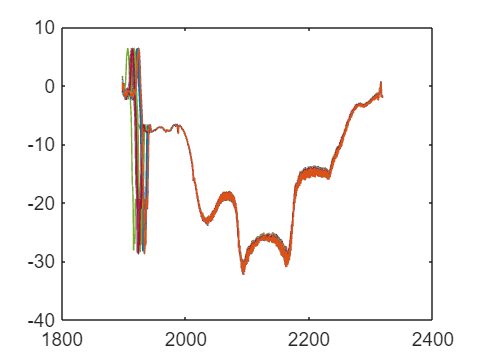


% Phase correction: Find pahse offset angle such that signal will be 
% contained as completely as possible within the x coordinate.
corrected=zeros([kb*128,repetitions]);
theta=zeros(repetitions,1);
for i=1:repetitions
    fun = @(p)sum(abs(x_matrix(:,i).*sin(p)-y_matrix(:,i).*cos(p)));
    p=fminbnd(fun,-pi,pi);   % can just set p=0 when phase correction is negligible
    theta(i)=p;
    if channel==2
        corrected(:,i)=x_matrix(:,i).*cos(p)+y_matrix(:,i).*sin(p);
    else
        corrected(:,i)=x_matrix(:,i).*cos(p+pi)+y_matrix(:,i).*sin(p+pi);   
    end
    % If signals are ever inverted from the expectation, 
    % may need to offset 180 degrees (add pi in cos and sin)
end

% Create frequency x-axis
t=transpose([0:length(x)-1]);
freq=startWL-t/capturerate*laser_rate;
adj_freq=1.005195.*freq-13.018819; % will usually be within 0.3 cm-1, recalibrated for wavelength trigger start
%%% adj_freq(1661:2048,:)=[]; % Remove data below 1980 cm-1
%%% corrected(1661:2048,:)=[]; % Remove data below 1980 cm-1 (old)

% Plot phase-corrected spectra
for i=1:repetitions
    p=plot(adj_freq,corrected(:,i));
    hold on
end
hold off


% Savitsky-Golay filter: 3rd order, 41 data points each time
% Can change filtering parameters as preferred.
sg = sgolayfilt(corrected,3,41); 

sgolayfilt requires Signal Processing Toolbox.


% Remove anomalous spectra using similarity indices
% Default cutoff parameters: 0.96 for mean across spectra, 0.8 for product
sg_mod=sg;
corr_coeff=corrcoef(sg);
mean_r=mean(corr_coeff,2);
remove_m=[];
for i=1:length(mean_r)
    if mean_r(i)<0.96 
        remove_m=[remove_m i];
    end
end
sg_mod(:,remove_m)=[]; 
corr_coeff_mod=corrcoef(sg_mod);
prod_r=prod(corr_coeff_mod,2);
remove_p=[];
for i=1:length(prod_r)
    if prod_r(i)<0.8
        remove_p=[remove_p i];
    end
end
sg_mod(:,remove_p)=[];
num_spectra=length(prod_r)-length(remove_p)

% Plot normal-looking, phase-corrected, SG-filtered spectra
figure()
for i=1:num_spectra
    p=plot(adj_freq,sg_mod(:,i));
    hold on
end
hold off

% Average the normal-looking, phase-corrected, SG-filtered spectra
x_avg=mean(sg_mod,2);

% Fourier filter with Blackman-Harris window
% Default is Order 400 FIR, 401 Blackman-Harris, 1000 Hz cutoff (very sharp)
L = numel(x_avg);                                           % Signal Length (Samples)
Fs = capturerate;                                           % Sampling Frequency
Fn = Fs/2;                                                  % Nyquist Frequency
t = linspace(0, L, L)/Fs;                                   % Time Vector
b = fir1(400, (1000/Fn), blackmanharris(401));               % Order 400 FIR LPF Fco = 1000 Hz
lp_filt = filtfilt(b,1,x_avg);                              % Filter Signal
figure
freqz(b,1, 2^12, Fs)                                        % Display Filter Bode Plot
% figure
% plot(t, x_avg)
% hold on
% plot(t, lp_filt)
% hold off
% grid

figure()
p2=plot(adj_freq,x_avg);
hold on
p2=plot(adj_freq,lp_filt);
hold off

% Convert voltage to power to account for nonlinear response
% Note that the calibration functions here need to be adjusted according to
% individual instruments.
% First record average voltage spectrum of ref channel saved as ref_V
cd(save_dir)
if channel==2  % For signal channel
    power=0.05961*lp_filt./(1-0.001432*lp_filt);     % In Microwatts
    sig_V=lp_filt;
    if has_sample==0   % for blanks
        power_sig_blank=power;
        save('power_sig_blank.mat','power_sig_blank');
    else   % for sample vs. blank
        power_sig_sample=power;
        save('power_sig_sample.mat','power_sig_sample');
    end
elseif channel==3  % For reference channel
    power=0.04264*lp_filt./(1-0.00153*lp_filt); % For reference channel
    ref_V=lp_filt;
    save('ref_V.mat','ref_V');
    power_ref=power;
    if has_sample==0
        save('power_ref_blank.mat','power_ref');
    else
        save('power_ref_sample.mat','power_ref');
    end
else % For balanced channel
    load(fullfile(save_dir,'ref_V.mat'));
    power=0.05961*(lp_filt+ref_V)./(1-0.001432*(lp_filt+ref_V))-0.04264*ref_V./(1-0.00153*ref_V);
    if has_sample==0
        power_bal_blank=power;
        save('power_bal_blank.mat','power_bal_blank');
        bal_V_blank=lp_filt;
        save('bal_V_blank.mat','bal_V_blank');
    else
        power_bal_sample=power;
        save('power_bal_sample.mat','power_bal_sample')
        bal_V_sample=lp_filt;
        save('bal_V_sample.mat','bal_V_sample');
    end
end
cd(run_dir)
% These calibration curves should work for 30% Duty cycle, 1 MHz pulse, and
% voltage less than 400 mV.

figure()
p3=plot(adj_freq,power);

Disarming Laser ... 

Successful


De-Initialize MIRcatSDK ... 

Successful


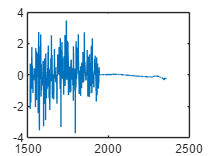

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                   Convert to Absorbance Spectrum                 %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if channel==1
    if has_sample==1
        cd(save_dir);
        load(fullfile(save_dir,'ref_V.mat'));
        load(fullfile(save_dir,'bal_V_blank.mat'))
        load(fullfile(save_dir,'bal_V_sample.mat'))
        A_bal=log10(0.05961*(bal_V_blank+ref_V)./(1-0.001432*(bal_V_blank+ref_V)))-log10(0.05961*(bal_V_sample+ref_V)./(1-0.001432*(bal_V_sample+ref_V)));
        % Another way of calculating absorbance uses just the
        % signal-channel power (no use of balanced detection):
        % A_simple=log10(power_sig_sample./power_sig_blank);
        
        % Convert to two-column format.
        A_bal_spectrum=[adj_freq,real(A_bal)];
        writematrix(A_bal_spectrum,'A_bal.txt');
        plot(adj_freq,A_bal);
    end
end